# 需求分析：离散粒子群算法求解函数极值问题

#### 粒子状态更新


$$s(v_{ij})=\frac{1}{1+exp(-v_{ij})}\\
\left\{
\begin{array}{l}
1,&rand<s(v_{ij})\\
0,&other
\end{array} 
\right.$$


clear;clc;
% 群体例子个数
N = 100; 
% 粒子维度
D = 20;             
T = 200;            % 最大迭代次数
c1 = 1.5;           % 学习因子1  
c2 = 1.5;           % 学习因子2
wMax = 0.8;         % 惯性权重最大值
wMin = 0.4;         % 惯性权重最小值
xMax = 10;          % 位置最大值
xMin =  -10;        % 位置最小值
vMax = 10;          % 速度最大值
vMin = -10;         % 速度最小值
%%%%%%%%%%  初始化种群个体（限定位置和速度） %%%%%%%%%
% 随机获得二进制编码的初始种群
x = randi([0, 1], N, D);   
v = rand(N, D) * (vMax - vMin) + vMin;
%%%%%%%%%%  初始化个体最优位置和最优值 %%%%%%%%%
p = x;
pbest = ones(N, 1);
for i = 1:N
   pbest(i) = ObjFunDiscrete(x(i, :), xMax, xMin);
end
%%%%%%%%%%  初始化全局最优位置和最优值 %%%%%%%%%
g = ones(1, D);
gbest = inf;
for i = 1:N
   if pbest(i) < gbest
      g = p(i, :);
      gbest = pbest(i);
   end
end
gb = ones(1, T);
vx = zeros(N, D);
%%%%%%%%%%  按照公式依次迭代直到满足精度或者迭代次数 %%%%%%%%%
for i = 1:T
   for j = 1:N
      %%%%%%%%%%  更新个体最优位置和最优值 %%%%%%%%%
      if ObjFunDiscrete(x(j, :), xMax, xMin) < pbest(j)
         p(j, :) = x(j, :);
         pbest(j) = ObjFunDiscrete(x(j, :), xMax, xMin);
      end
      %%%%%%%%%%  更新全局最优位置和最优值 %%%%%%%%%
      if pbest(j) < gbest
         g = p(j, :);
         gbest = pbest(j);
      end
      %%%%%%%%%%  动态计算惯性权重值 %%%%%%%%%
      w = wMax - (wMax - wMin) * i / T;
      %%%%%%%%%%  更新位置和速度值 %%%%%%%%%
      v(j, :) = w * v(j, :) + c1 * rand * (p(j, :) - x(j, :)) + c2 * rand * (g - x(j, :));
      x(j, :) = x(j, :) + v(j, :);
      %%%%%%%%%%  边界条件处理 %%%%%%%%%
      for ii = 1:D
         if (v(j, ii) > vMax) || (v(j, ii) < vMin)
            v(j, ii) = rand * (vMax - vMin) + vMin;
         end
      end
      vx(j, :) = 1 ./ (1 + exp(-v(j, :)));
      for jj = 1 : D
         if vx(j, jj) > rand
            x(j, jj) = 1;
         else
            x(j, jj) = 0;
         end
      end
   end
      %%%%%%%%%%  记录历代全局最优值 %%%%%%%%%
      gb(i) = gbest;
end
m = 0;
for j = 1:D
   m = m + g(j) * 2^(j - 1);
end
f1 = xMin + m * (xMax - xMin)/(2^D - 1);
disp(['最优个体：' num2str(f1)]);

最优个体：-8.1947


disp(['最优值：' num2str(gb(end))]);

最优值：-22.9862


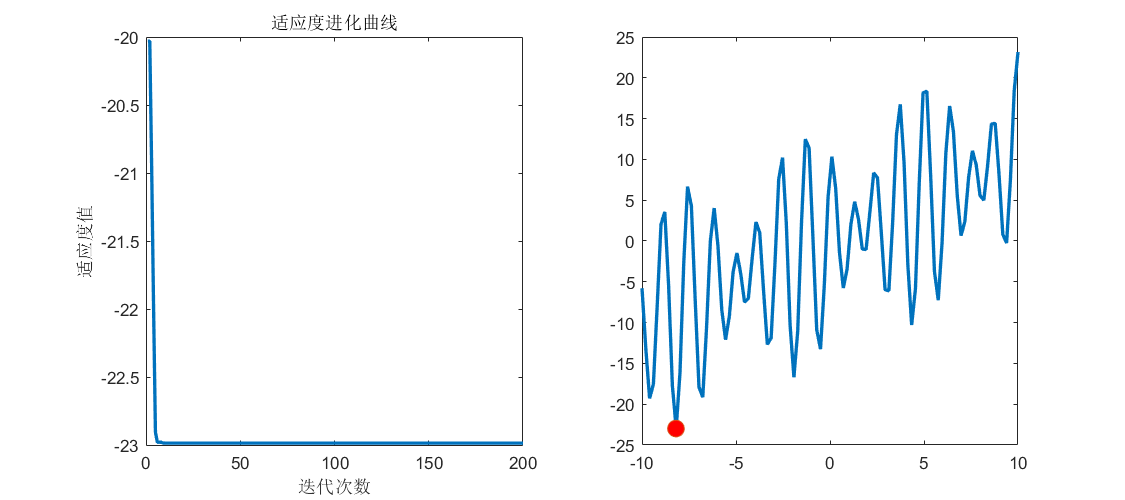

subplot(1, 2, 1);
plot(gb, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度进化曲线');
subplot(1, 2, 2)
xRange = linspace(xMin, xMax, 100);
yRange = xRange + 6 * sin(4 * xRange) + 9 * cos(5 * xRange);
plot(xRange, yRange, 'LineWidth', 2);
hold on;
plot(f1, gb(end),'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off;
set(gcf, 'Position', [400, 200, 900, 400]);